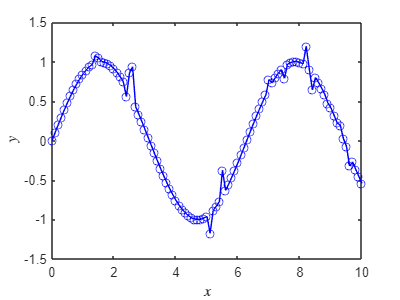

% Data generation
x = [0:0.1:10]' ;
y = sin(x) ;

% Introduction of random outliers
ind = randi(numel(y),15,1) ;
y(ind) = y(ind) + rand(size(ind))-0.5 ;

f1 = figure ;
f1.Position(3:4) = [400 300] ;
plot(x,y,'b-o') ;
xlabel("$x$","Interpreter","latex") ;
ylabel("$y$","Interpreter","latex") ;
ylim([-1.5 1.5]) ;

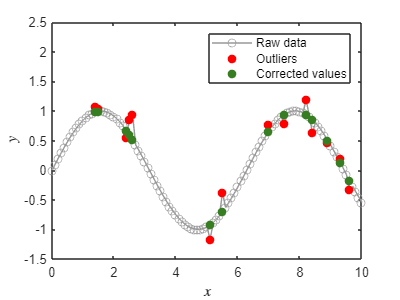


% Smooting with robust options
[y_smoothed, noise] = sgolay_robust(y,10,3,1) ;
ind = find(abs(y_smoothed-y)>=3*noise) ;

f2 = figure ;
f2.Position(3:4) = [400 300] ;
plot(x,y,'-o','Color',[0.6 0.6 0.6]) ; hold on ;
plot(x(ind),y(ind),'ro','MarkerFaceColor','r') ;
plot(x(ind),y_smoothed(ind),'o','Color',[55 125 34]/255,'MarkerFaceColor',[55 125 34]/255) ;
hold off ;
ylim([-1.5 2.5]) ;
xlabel("$x$","Interpreter","latex") ;
ylabel("$y$","Interpreter","latex") ;
legend(["Raw data" ; "Outliers" ; "Corrected values"]) ;